Definition of the cube

% Define Corners
 A = [0 0 0];
 B = [1 0 0];
 C = [0 1 0];
 D = [0 0 1];
 E = [0 1 1];
 F = [1 0 1];
 G = [1 1 0];
 H = [1 1 1];
cube = [A;B;F;H;G;C;A;D;E;H;F;D;E;C;G;B]-0.5; % cube created


Quaternions

angle = 30;
unitVector = [0;1;0]

unitVector =      0
     1
     0


quaternion = QuaternionFromAngleAndUnitVector(angle,unitVector);

cubeSize = size(cube);
for i = 16
    vector = cube(i,:)
    newVector = VectorRotationByQuaternion(quaternion,vector);
   % cube(i,:) = newVector;
end

vector =     0.5000   -0.5000   -0.5000


qc = -0.7597

qc =    -0.7597         0


qc =    -0.7597         0   -0.6503


qc =    -0.7597         0   -0.6503         0


qc =    -0.7597         0   -0.6503         0


vr = 0

vr =          0    0.2114


vr =          0    0.2114         0


Euler principal Angle and Axis 

%TODO
axis = [1;0;0]

axis =      1
     0
     0


angle = 0;
matrix = RotationMatrix(axis,angle);

Rxyz =      1     0     0
     0     1     0
     0     0     1


ans = 1

Y =      1     0     0
     0     1     0
     0     0     1


ans =      1     0     0
     0     1     0
     0     0     1


I =      1     0     0
     0     1     0
     0     0     1


for i = 3
   % cube(i,:) = matrix(i,:) .* cube(i,:);
end


Euler Angles

roll = 360

roll = 360

pitch = 360

pitch = 360

yaw =0

yaw = 0

dcm = angle2dcm(yaw, pitch, roll);
%cube = cube*dcm;


 Rotation vector

%TODO
vector = [1;0;1]

vector =      1
     0
     1


axis = [0;1;0]

axis =      0
     1
     0


angle = norm(vector);
for i = 3
axis(i) = vector(i) / angle; 
end

matrix = RotationMatrix(axis,angle);

Rxyz =     0.1559   -0.6985    0.9878
    0.6985    1.0000    0.5968
   -0.9878    0.5968    0.5780


ans = 2.1158

for i = 3
cube(i,:) = matrix(i,:) * cube(i,:);
end

Rotation Matrix

%TODO: print rotation matrix
disp(cube);

   -0.5000   -0.5000   -0.5000
    0.5000   -0.5000   -0.5000
   -0.4939   -0.2984    0.2890
    0.5000    0.5000    0.5000
    0.5000    0.5000   -0.5000
   -0.5000    0.5000   -0.5000
   -0.5000   -0.5000   -0.5000
   -0.5000   -0.5000    0.5000
   -0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000
    0.5000   -0.5000    0.5000
   -0.5000   -0.5000    0.5000
   -0.5000    0.5000    0.5000
   -0.5000    0.5000   -0.5000
    0.5000    0.5000   -0.5000
    0.5000   -0.5000   -0.5000



Draw cube

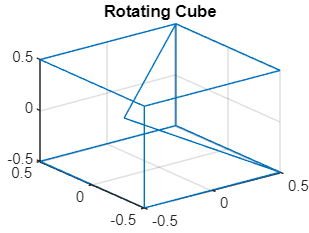


plot3(cube(:,1),cube(:,2),cube(:,3));
grid on
title('Rotating Cube')